# Spike Artifacts

Investigate how tACS stimulation artifacts affect spike recordings.

## Setup Simulation

Simulation parameters

spk = artSim;                           % Start with default parameters
spk.duration                  = 120;    % 2 min
spk.stimulatorSamplingRate    = 1e3;     % e.g., Starstim (1 kHz)
spk.currentResolution         = 1e-6;    % 1 muA
spk.tacsAmplitude             = 1e-3;    % 1 mA
spk.resistance                = 1;        % 1 mA -> 1 mV artifact
spk.tacsFrequency             = 40;      % 10 Hz
spk.recordingSamplingRate     = 30e3;     % 30kHz
spk.adcLinearRange            = 6.8e-3;   % Linear range of amplified 6.8 mV
spk.adcNonlinearity           = 100;      % Piecewise linear
spk.adcRange                  = 10e-3;     % Input range of the ADC.
spk.adcBitDepth               = 16;       % Number of bits in the AD convertor
spk.adcGain                   = 20;       % Amplify 20x
spk.reproducible              = true;     % Reseed the RNG to get reproducible results

Define the common neural signals

spk.spikePeak                 = 60e-6;   % 100 muV
spk.spikeRate                 = 100;      % 100 spk/s
spk.poisson                   = true;     % Poisson spiking
spk.fixNrSpikes               = true;     % Deviate from Poisson to get exact firing rate.
spk.refractoryPeriod          = 1.5e-3;   % 1.5 ms
spk.additive                  = 20e-6;    % Background activity/noise
spk.pinkNoise                 = true;     % Pink background noise


Define the common parameters for artifact removal

ar.nrCycles                  = 30;      % 30 cycles per segment
ar.slide                     = false;   % No sliding segment
ar.slack                     = 5e-3;    % 5 ms to realign segments
ar.nrSegsPerWindow           = 10;      % 10 segments to average artifact
ar.pcaNr                     = 2;       % First two PC are removed
ar.pcaVarExplained           = Inf;     % Ignore explained variance, always remove 2.
ar.pcaNrSegsPerWindow        = Inf;     % Use all segments (plus the tACS signal; below) to determine basis set.
ar.referenceSegment          = 1;       % Align to first segment

Set the tACS frequencies to investigate.

tacsFreqs                    = [2 5 10 20 40];
nrTacsFreqs                  = numel(tacsFreqs);

Define the filter that extract signals in the "spike band":

lowCut                      = 500;  % high pass filter cut off
highCut                     = 7000; % Low pass filter cut off.
filterOrder                 = 3; % Filter order  (Butterworth)

## Stimulator Discretization Artifacts

With typical tACS frequencies below 100 Hz and typical spiking signals near 1 kHz, one might expect that a simple high-pass filter would remove all tACS artifacts from the signal used for spike-based analysis. This is indeed the case for an ideal stimulator that genreates sinusoidal waveforms with high temporal resolution. Stimulators, however, typically use a sampled D2A converter to generate currents and such sampled sinusoids can generate artifacts in the spike band. 

To illustrate this I simulated a stimulator with a 1 kHz sampling rate, and 1 muA current resolution. 


spk.stimulatorSamplingRate    = 1e3;     % Starstim (1 kHz)
spk.currentResolution         = 1e-6;    % 1 muA

Generate a tACS artifact:

spk.tacsAmplitude             = 1e-3;    % 1 mA for illustration
spk.tacsFrequency             = 40;
spk.tacsPhaseOffset           = 0.5*pi;
spk.reset;
spk.simtACS;

The simulation has now created the `vTacsActual `- the voltage artifact created by this stimulator. 

Visualizing just two cycles of the waveform illustrates the problem: 

[~,axs] = fig('Name','stimArtifacts.Fig7','paperCols',2,'height',9,'nrRows',2,'nrCols',3,'byColumn',false);

Show the voltage artifact

nrCyclesToShow = 2;
axes(axs(1))
plot(spk.tSimulate/1e-3,spk.vTacsActual/1e-3)
xl = [0 nrCyclesToShow/spk.tacsFrequency/1e-3];
xlim (xl);
xlabel 'Time (ms)'
ylabel 'Voltage (mV)'
axs(1).XTick = xl;


and its amplitude spectrum

axes(axs(2))
[ft,frequency]= fftReal(spk.vTacsActual(:),spk.quasiContinuousSamplingRate);
amplitude =abs(ft)./(2*numel(spk.vTacsActual));

plot(frequency/1e3,amplitude/1e-6);
xlabel 'Frequency (kHz)'
ylabel 'Amplitude (\muV)'
xlim([lowCut highCut]/1e3)

The spectral power shows that the artifact is not stationary, but varies with tACS phase

axes(axs(3))
% Spectrogram
boundaryCycles =4;
samplesPerCycle = spk.quasiContinuousSamplingRate./spk.tacsFrequency;
keep = 1:round(nrCyclesToShow*samplesPerCycle)+boundaryCycles*samplesPerCycle;
x = spk.vTacsActual(keep);
[ft,freq]= fftReal(x,spk.quasiContinuousSamplingRate);
ft(freq<lowCut | freq>highCut) =0;
x = ifftReal(ft,freq,spk.quasiContinuousSamplingRate);
pspectrum(x,spk.quasiContinuousSamplingRate,'spectrogram','FrequencyResolution',500,'FrequencyLimits',[0 highCut])

xlim([50 100])
axs(3).XTick =[50 75 100];
axs(3).YTick =[lowCut/1e3 1:highCut/1e3];
axs(3).XTickLabel = {'0','25','50'};
ylim([lowCut highCut]/1e3)
colorbar('off')
title ''
colormap hot

Add a polar representation of the peak of the artifact to emphasize the phase dependence

trgPos = get(axs(4),'Position');
trgPos([1 2]) = trgPos([1 2]).*[0.7 0.9];
 % trgPos([3 4]) = trgPos([3 4])/2;
 pax = polaraxes('Position',trgPos);
axes(pax);
[P,F,T] = pspectrum(x,spk.quasiContinuousSamplingRate,'spectrogram','FrequencyResolution',500,'FrequencyLimits',[0 highCut]);
oneCycle =T>=3/spk.tacsFrequency & T< 4/spk.tacsFrequency;

P =sum(P(:,oneCycle)); % Sum one cycle over the spike band
phase = spk.tacsPhaseOffset+ linspace(0,2*pi*(1-1/numel(P)),numel(P)+1);
P = [P P(1)];
polarplot(phase,P)

pax.RTick = [];
pax.ThetaTick = [0 90 180 270];
%pax.ThetaTickLabel = [];
pax.Color = 'w';
delete(axs(4))


And illustrate that the power in the spike band increases (linearly) with the tACS frequency


artifactPower = nan(nrTacsFreqs,1);
for i = 1:nrTacsFreqs
    spk.tacsFrequency             =tacsFreqs(i);
    spk.reset;
    spk.simtACS;
    [ft,frequency]= fftReal(spk.vTacsActual(:),spk.quasiContinuousSamplingRate);
    % Remove the power that would be filtered out
    ft(frequency < lowCut | frequency > highCut) = 0;
    signal = ifftReal(ft,frequency,spk.quasiContinuousSamplingRate);
    artifactPower(i) = max(abs(signal));
end
axes(axs(5))
plot(tacsFreqs,artifactPower./1e-6)
xlabel 'tACS Frequency (Hz)'
ylabel 'Artifact (\muV)'

Finally, show the shape of the artifact at selected tACS phases.

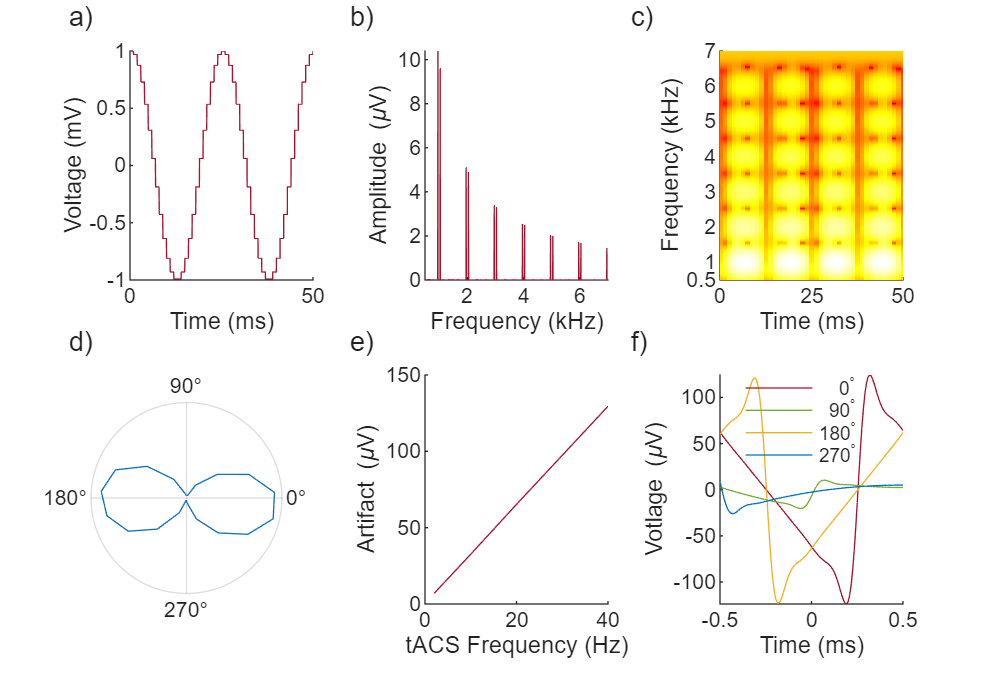


samplesPerCycle = spk.quasiContinuousSamplingRate./spk.tacsFrequency;
axes(axs(6))
% Bandpass filter to take only the signal in the spike band
[B,A] = butter(filterOrder,[lowCut highCut]/(spk.quasiContinuousSamplingRate/2),'bandpass');
filteredVoltage   = filtfilt(B,A,spk.vTacsActual(:));
% Select a time window similar to a spike 
samplesToShow     = 1e-3*spk.quasiContinuousSamplingRate; %  1 ms
samplesBefore     = round(0.5*samplesToShow);
samplesAfter      = samplesToShow-samplesBefore;
phase             = [0 90 180 270];
offset            = round(samplesPerCycle*(rad2deg(2*pi-spk.tacsPhaseOffset)/360));
t                 = (-samplesBefore:samplesAfter)/spk.quasiContinuousSamplingRate;
for ph=phase
    ix = offset+ round(samplesPerCycle*ph/360) + (-samplesBefore:samplesAfter);
    plot(t/1e-3,filteredVoltage(ix)/1e-6);
    hold on
end
xlabel 'Time (ms)'
ylabel 'Votlage (\muV)'
legend(string(num2str(phase')) + "^\circ","Position", [0.74 0.31 0.12, 0.14])
legend('boxoff')

## Spike Sorting 

Spike sorting labels spikes as belonging to a specific neuron and is often used to focus analysis on one (or more) identified neurons with recognizable wave forms. This process is standard, but in the context of stimulation artifacts, there is a potential that the spike sorting procedure masks (rather than removes) the effects of stimulation. These simulations explore that using the UMS2K spike sorter (although the details of spike sorting are unlikely to change the overall message).

Define the neural signals:

spk.synchrony                 = 0;        % Poisson random spikes, no relation with LFP
spk.lfpAmplitude              = 0;        % No intrinsic oscillation
spk.multiplicative            = 0;        % No multiplicative noise
spk.tacsAmplitude             = 80e-6;   % A->V artifact
spk.reproducible              = 2;        % Set the seed

Define spike sorting  parameters.

In most approaches, the spike detection threshold is defined relative to some noise level that is estimated from the signal in the spike band. The simulations generate one trial with tACS and one trial without tACS (but the same spikes). By setting `sharedThreshold `to `true, the v`oltage threshold is estimated from the concatenated signals in the spike band (i.e., with and without tACS).  Note that this creates an interaction between spike detection in trials with and without tACS. Notably, if tACS generates large artifacts in the spike band, the voltage threshold will be high and true spikes -even in trials without stimulation -  could be lost  resulting in false negatives even in sham trials. 

The spike detection can be changed to use a separate threshold for stimulated and non-stimulated trials (`sharedThreshold = false`) - although this creates its own issues in the interpretation of the results.

threshold                      = 3.5 ; % Spikes are defined as this many standard deviations above zero.
sharedThreshold                = true;

After spike detection, UMS2K extracts a waveform for each spike to determine clusters based on the waveform shape. (This too leads to an interaction between tACS contaminated and tACS-free spikes).

nrPre                           = 1e-3*spk.recordingSamplingRate; % Samples to keep before threshold crossing
nrPost                          = nrPre; % Samples to keep after threshold crossing

ArtSim can use different methods to do spike sorting. ALL  means no spike sorting; it returns all threshold crossings. In MATCHSHAM mode, spikes in the tACS trial are compared to the clusters found in the no-tACS trial and assigned to the best-matching cluster. MOSTSPIKES keeps only the unit with the most spikes. Investigate spike detection first:

spikeSortingMode                ="ALL";

Run the simulation to illustrate the problem caused by stimulation artifacts in a pipeline that only filters to the spike band (i.e. without other artifact removal). 

[~,axs] = fig('Name',"SpikesNOPAll.Fig8",'paperCols',2,'height',12,'nrRows',2,'nrCols',2,'byColumn',false);   

[sortResultsNopAll]  = simPlotSpikes(spk,ar,"NOP",xlim = 8+[0 0.1],lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,sharedThreshold = sharedThreshold, spikeSortingMode=spikeSortingMode,axs=[axs(1:2)' gobjects(2)]);

********QC********* 
 Starting Values: MSE = 2.29e+03 muV , r= 0.176
	 After NOP: MSE = 92.4 muV , r= 0.930
Detected on average 97.2292 events per second of data 
False Positive. Sham: 0%  tACS: 1% 
False Negative. Sham: 1%  tACS: 5% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.01 


This figure shows the voltage trace filtered to the spike band (red), the ground truth spikes (circle), and the detected spikes (asterisk) for a snippet from the no-tACS trial (a) and the tACS trial (b). Panel c shows a polar histogram of the spikes as a function of the phase of tACS.  In the sham trial all phases are equally likely, in the tACS trial, the 180 degree phase is less likely to result in a detected spike. Panel d shows that the average waveform of the sorted spikes does not depend on the phase. 

The phase dependence arises due to the larger current steps near the 180 and 0 phases, and the difference between 180 and 0 is the result of the spike threshold detection algorithm; UMS2K detects negative going crossings of the (negative) threshold. Because the 180-phase tACS transitions produce negative going "noise", the


spikeSortingMode                ="MATCHSHAM";

Run the simulation to illustrate the problem caused by stimulation artifacts in a pipeline that only filters to the spike band (i.e. without other artifact removal). 

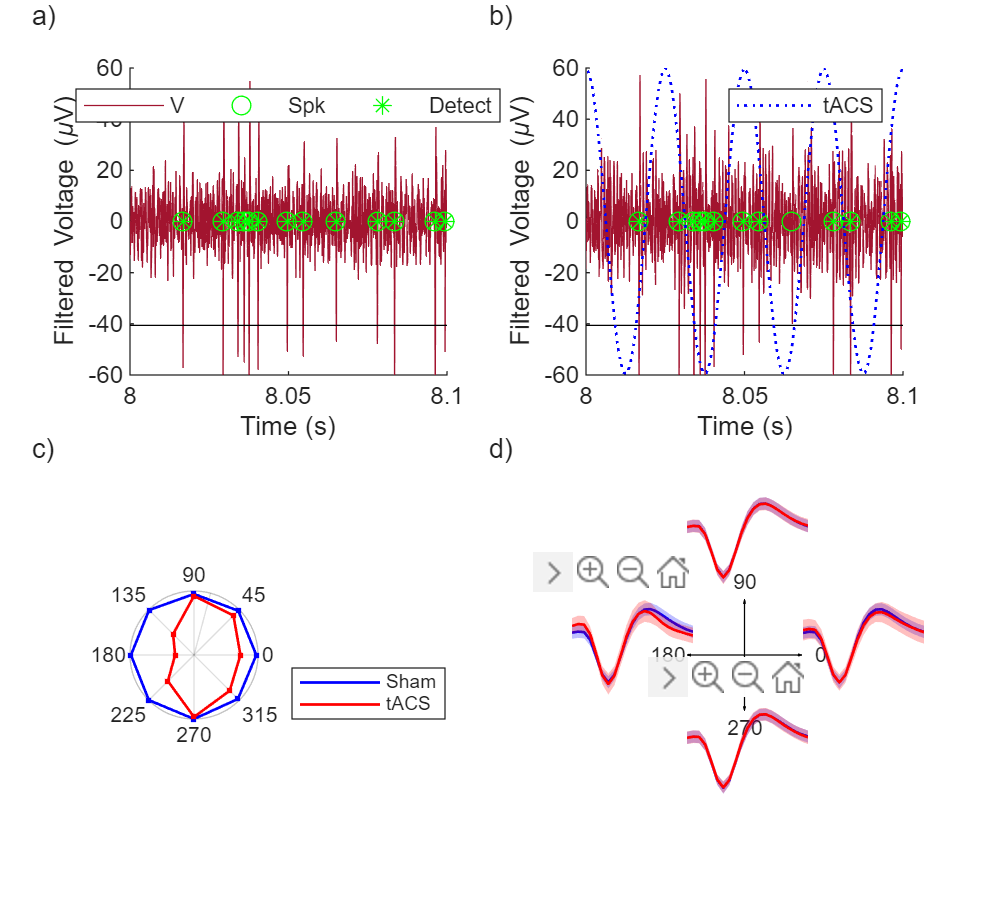

********QC********* 
 Starting Values: MSE = 2.29e+03 muV , r= 0.176
	 After NOP: MSE = 92.4 muV , r= 0.930
Detected on average 97.2292 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 2%  tACS: 29% 
PLV. Sham: 0.00  tACS: 0.15 
PLV2. Sham: 0.00  tACS: 0.18 


 [sortResultsNop]  = simPlotSpikes(spk,ar,"NOP",lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,sharedThreshold = sharedThreshold, spikeSortingMode=spikeSortingMode,axs=[gobjects(1:2) axs(3:4)]);

In these simulations there are no false positive  (i.e. sorted spikes found where none were simulated), but false negatives are quite frequent; not only in the tACS trial (28%), but also in the Control/Sham trial (8%). The latter is a consequence of using a single spike threshold and spike template estimation - this results in a contamination of the spike sorting process in the sham trial.

Taken together, these stimulation show that merely filtering to the spike band is not sufficient to remove spike artifacts. 

### Spike Sorting with FASTR 

Run the same spike sorting pipeline now with FASTR recovery of the underlying neural signal. 

********QC********* 
 Starting Values: MSE = 2.29e+03 muV , r= 0.176
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 9 sec.
	 After FASTR: MSE = 117 muV , r= 0.918
Detected on average 99.6042 events per second of data 


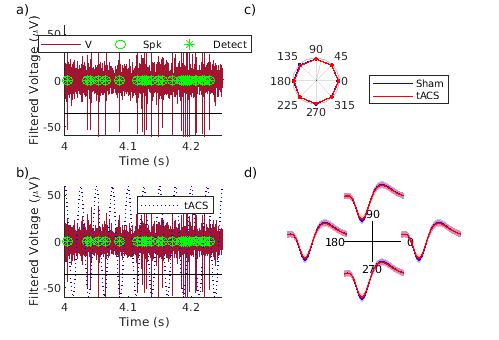

False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 1% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 


  [sortResultsFASTR] = simPlotSpikes(spk,ar,"FASTR",lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode);

This shows FASTR helps to recover true spiking. But note that some false negatives remain.  

### Spike sorting with RBAR

********QC********* 
 Starting Values: MSE = 2.29e+03 muV , r= 0.176
	 After RBAR: MSE = 5.97 muV , r= 1.000
Detected on average 99.8417 events per second of data 


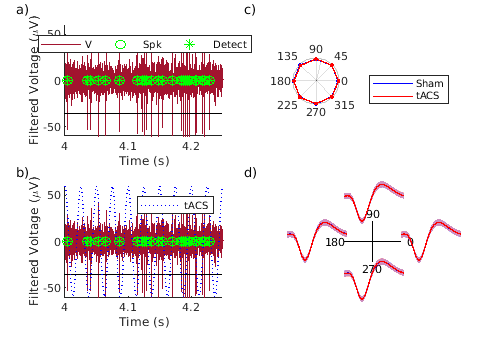

False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 


[sortResultsRBAR] = simPlotSpikes(spk,ar,"RBAR",lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode);

RBAR recovers the spikes; with zero false negatives.

### Frequency dependence

The spectral analysis (above) shows that the contamination of the spike band depends on the frequency of tACS. Here I investigate how how different tACS frequencies affect the fraction of false negatives (for the current choices of neural signal, noise, and thresholds, the false positive rate is negligible).

methods  =["NOP" "FASTR" "RBAR"];
spk.tacsAmplitude  = 2e-4;    % A->V artifact
nrMethods = numel(methods);
falsePositive = nan(2,nrTacsFreqs,nrMethods);
falseNegative = nan(2,nrTacsFreqs,nrMethods);
oldState =[];
for m=1:nrMethods
    for i=1:nrTacsFreqs
        spk.tacsFrequency = tacsFreqs(i);
        [~,falsePositive(:,i,m),falseNegative(:,i,m)] = simPlotSpikes(spk,ar,methods(m),lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode,axs=gobjects(4));        
    end
end

********QC********* 
 Starting Values: MSE = 5.6e+03 muV , r= 0.044
	 After NOP: MSE = 14.8 muV , r= 0.998
Detected on average 99.8417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.58e+03 muV , r= 0.063
	 After NOP: MSE = 31.1 muV , r= 0.992
Detected on average 99.7167 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.6e+03 muV , r= 0.071
	 After NOP: MSE = 59.9 muV , r= 0.971
Detected on average 99.2125 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 7%  tACS: 26% 
PLV. Sham: 0.00  tACS: 0.03 
PLV2. Sham: 0.00  tACS: 0.14 
********QC********* 
 Starting Values: MSE = 5.77e+03 muV , r= 0.072
	 After NOP: MSE = 120 muV , r= 0.897
Detected on 

Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
.25% .50% .75% .100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 10 sec.
	 After FASTR: MSE = 121 muV , r= 0.866
Detected on average 78.1792 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 47% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.58e+03 muV , r= 0.063


Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 11 sec.
	 After FASTR: MSE = 72.6 muV , r= 0.946
Detected on average 94.4375 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 11% 
PLV. Sham: 0.01  tACS: 0.01 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.6e+03 muV , r= 0.071
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 9 sec.
	 After FASTR: MSE = 82.4 muV , r= 0.955
Detected on average 99.1958 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 2% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.77e+03 muV , r= 0.072
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
	 After FASTR: MSE = 104 muV , r= 0.929
Detected on average 99.2875 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 1% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.070
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
	 After FASTR: MSE = 117 muV , r= 0.914
Detected on average 99.6208 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 1% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.6e+03 muV , r= 0.044
	 After RBAR: MSE = 4.7 muV , r= 1.000
Detected on average 99.8417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 5.58e+03 muV , r= 0.063
	 After RBAR: MSE = 8.22 muV , r= 0.999
Detected on average 99.8417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE 

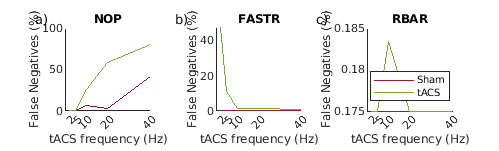


[f,ax] = fig('Name','frequency','paperCols',2,'height',4,'nrRows',1,'nrCols',3);
for method =1:nrMethods
    axes(ax(method))
    hold on
    plot(tacsFreqs,falseNegative(:,:,method)','LineStyle','-');
    xlabel 'tACS frequency (Hz)'
    ylabel 'False Negatives (%)'
    set(gca,'XTick',tacsFreqs);
    title (methods(method))
    
end
legend ('Sham','tACS','Location','south')

### Interactions

The simulations above show a non zero false negative rate after FASTR and that the tACS signal affects the results in the non-tACS trials (due to the shared voltage threshold and waveform clustering procedure). The percentages shown depend on the randomization; to quantify an average effect, I bootstrapped this.

spk.tacsFrequency = 40; % Example frequency
spk.tacsAmplitude  = 2e-4;    % A->V artifact
spk.reproducible = false; % Do not reset the RNG
nrBootstraps = 100;
falseNegFastr= nan(2,nrBootstraps);
% Use a parfor as this takes a while
parfor i=1:nrBootstraps        
    [~,~,falseNegFastr(:,i)] = simPlotSpikes(spk,ar,"FASTR",lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode,axs=gobjects(4));        
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.071
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.072
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.073
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.071
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.071
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.075
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.072
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.074
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.072
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.074
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.072
********QC********* 
 Starting Values: MSE = 5.76e+03 muV , r= 0.068
Allocating memory...
Allocating memory...
Allocating 

Error using artSim/sortSpikes (line 1040)
Array indices must be positive integers or logical values.

Error in artSim/simPlotSpikes (line 722)
            [sortResults,spikes] =sortSpikes(o,vRecovered,...

[~,axs] = fig('Name','Interactions','nrRows',1,'nrCols',2);
axes(axs(1))
mFalseNegFastr = mean(falseNegFastr,2,"omitmissing");
sdFalseNegFastr = std(falseNegFastr,0,2,"omitmissing");
bar(mFalseNegFastr);
hold on
errorbar(mFalseNegFastr,sdFalseNegFastr,'.')
set(gca,'XTick',1:2,'XTickLabel',{'Sham','tACS'});
ylabel ('False Negatives (%)');
axes(axs(2))
plot(falseNegFastr(2,:),falseNegFastr(1,:),'.')
xlabel 'tACS'
ylabel 'Sham'
r= corrcoef(falseNegFastr');
title (sprintf('Cross Contamination: r = %.2f',r(1,2)));

## Amplifier Saturation

spk.adcNonlinearity           = 4;   % Sigmoidal
spk.tacsAmplitude             = 80e-6;  
spk.resistance                = 35;  % Increase artifact size to reach the nonlinear range.
spk.reproducible              = true; 
spk.stimulatorSamplingRate    = 1e6;
spikeSortingMode              = "ALL";

Run the same simulation as above -only the amplification has changed.

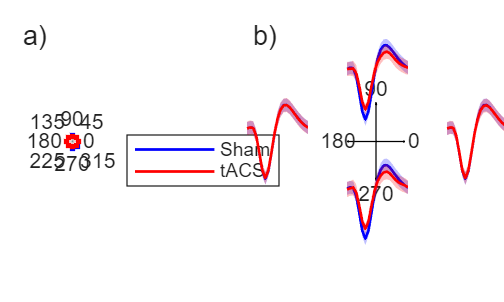

********QC********* 
 Starting Values: MSE = 7.63e+04 muV , r= 0.005
	 After NOP: MSE = 2.08e+03 muV , r= 0.160
Detected on average 94.8583 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 10% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.08 


[~,axs] = fig('Name',"NonlinearAmplification.Fig9",'paperCols',1,'height',4,'nrRows',1,'nrCols',2,'byColumn',true);
[sortResultsRBARNonLin] = simPlotSpikes(spk,ar,"NOP",nrPhaseBins =8, phaseFromRaw = true,lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode,axs=[gobjects(1:2)';axs]);

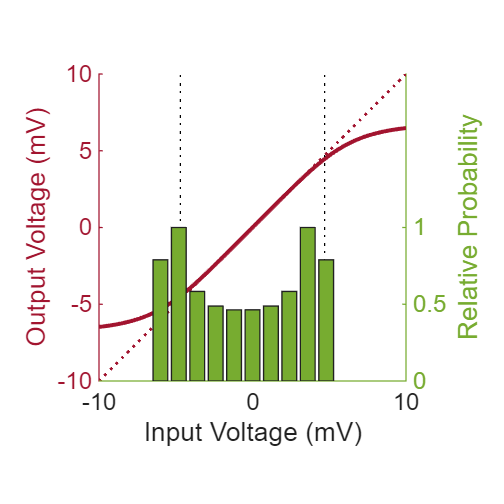


fig('Name','AmpTransfer.Fig10','nrRows',1,'nrCols',1);
yyaxis left
in = linspace(-spk.adcRange,spk.adcRange,100);
[out,satPoint] = artSim.amplify(in,spk.adcLinearRange,spk.adcNonlinearity,spk.adcGain,satLevel = 95);
scale = (1e-3*spk.adcGain);
plot(in/1e-3,out/scale,'LineWidth',1.5)
hold on
plot(in/1e-3,in/1e-3,'LineWidth',1,'LineStyle',':')
xlabel 'Input Voltage (mV)'
ylabel 'Output Voltage (mV)'
plot(satPoint/1e-3*[1 1],ylim,'k:')
plot(-satPoint/1e-3*[1 1],ylim,'k:')

[n,vBins] = histcounts(spk.vContaminated/scale,10);
yyaxis right
bar(vBins(1:end-1),n./max(n));
ylim([0 2]);
set(gca,'YTick',[0 0.5 1])
ylabel 'Relative Probability'

axis square; 